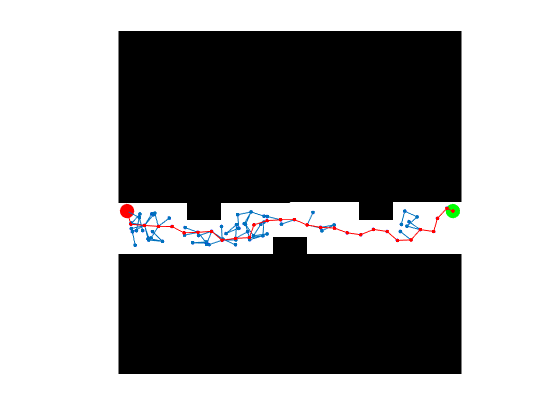

clear all; close all;
x_I=1; y_I=11;           % 初始点
x_G=20; y_G=11;       % 目标点
goal(1)=x_G;
goal(2)=y_G;
Thr=0.5;                 %设置目标点阈值
Delta= 0.8;              % 设置扩展步长
%% 建树
T.v(1).x = x_I;         
T.v(1).y = y_I; 
T.v(1).xPrev = x_I;     
T.v(1).yPrev = y_I;
T.v(1).dist=0;          
T.v(1).indPrev = 0;     

figure(1);
Imp=[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;  
   1 1 1 1 0 0 1 1 1 1 1 1 1 1 0 0 1 1 1 1; 
   1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1; 
   1 1 1 1 1 1 1 1 1 0 0 1 1 1 1 1 1 1 1 1;
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;];

imshow(Imp,'InitialMagnification','fit')
xL=size(Imp,1);
yL=size(Imp,2);
hold on
plot(x_I, y_I, 'ro', 'MarkerSize',10, 'MarkerFaceColor','r');
plot(x_G, y_G, 'go', 'MarkerSize',10, 'MarkerFaceColor','g');


count=1;
for iter = 1:3000
    p_rand=[];
    p_rand(1)=rand()*xL; 
    p_rand(2)=2*rand()+11;
    
    p_near=[];
    min_distance = 1000;
    for i=1:count
        distance = sqrt( ( T.v(i).x - p_rand(1) )^2 + ( T.v(i).y - p_rand(2) )^2 );
        if distance < min_distance
            min_distance = distance;
            index = i;
        end
    end
    p_near(1) = T.v(index).x;
    p_near(2) = T.v(index).y;
    
    p_new=[];
    p_new(1) = p_near(1) + roundn(( p_rand(1)-p_near(1) ) * Delta/min_distance,-2) ;
    p_new(2) = p_near(2) + roundn(( p_rand(2)-p_near(2) ) * Delta/min_distance,-2) ;
    
    %检查节点是否是collision-free
    if ~collisionChecking(p_near,p_new,Imp) 
       continue;
    end
    count=count+1;
    
    T.v(count).x = p_new(1);         
    T.v(count).y = p_new(2); 
    T.v(count).xPrev = p_near(1);    
    T.v(count).yPrev = p_near(2);
    T.v(count).dist = min_distance;          
    
    new_distance = sqrt( ( p_new(1) - x_G )^2 + ( p_new(2) - y_G )^2 );
    if new_distance <= Thr
        plot(p_new(1), p_new(2), 'bo', 'MarkerSize',2, 'MarkerFaceColor','b'); % 绘制x_new
        line( [p_new(1) p_near(1)], [p_new(2) p_near(2)], 'Marker','.','LineStyle','-'); %连接x_near和x_new
        line( [x_G p_new(1)], [y_G p_new(2)], 'Marker','.','LineStyle','-'); %连接x_Target和x_new
        break;
    end
    
    
    plot(p_new(1), p_new(2), 'bo', 'MarkerSize',2, 'MarkerFaceColor','b'); % 绘制x_new
    line( [p_new(1) p_near(1)], [p_new(2) p_near(2)], 'Marker','.','LineStyle','-'); %连接x_near和x_new
    hold on;
   
    pause(0.1); %暂停0.1s
end
 
%% 画出路径
T_LIST = zeros(size(T.v, 2), 5);
for i=1:size(T.v, 2)
    T_LIST(i,1) = T.v(i).x;
    T_LIST(i,2) = T.v(i).y;
    T_LIST(i,3) = T.v(i).xPrev;
    T_LIST(i,4) = T.v(i).yPrev;
    T_LIST(i,5) = i;
end
 
path = [];
path_count = 1;
path(path_count,1) = x_G;
path(path_count,2) = y_G;
path_count = path_count + 1;
path(path_count,1) = p_new(1);
path(path_count,2) = p_new(2);
n_index = node_index(T_LIST, p_new(1), p_new(2));
path_count = path_count + 1;
path(path_count,1) = T_LIST(i,3);
path(path_count,2) = T_LIST(i,4);
while path(path_count,1) ~= x_I || path(path_count,2) ~= y_I
    new_n_index = node_index(T_LIST, path(path_count,1), path(path_count,2));
    path_count = path_count + 1;
    path(path_count,1) = T_LIST(new_n_index,3);
    path(path_count,2) = T_LIST(new_n_index,4);
    n_index = new_n_index;
end
 
for i=size(path,1)-1 :-1: 1
    line( [path(i,1) path(i+1,1)], [path(i,2) path(i+1,2)], 'Marker','.','LineStyle','-','color','r'); %连接x_near和x_new
    hold on;
    pause(0.1); %暂停0.1s，使得RRT扩展过程容易观察
end